Q-5

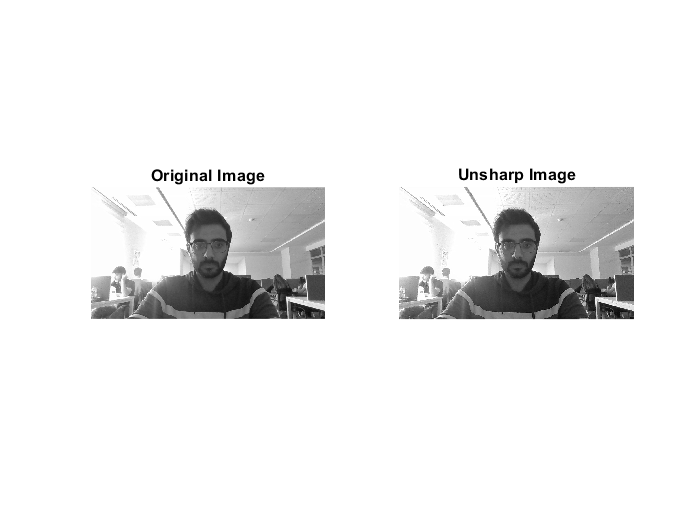

ahmet=imread('ahmet.jpg');
ahmet_g=rgb2gray(im2double(ahmet));

mask=ones(3,3);
masknorm=mask/sum(mask(:));

imavg=imfilter(ahmet_g,masknorm);
unsharp_ahmet_g=2*ahmet_g - imavg;

subplot(1,2,1);
imshow(ahmet_g);
title('Original Image');

subplot(1,2,2);
imshow(unsharp_ahmet_g);
title('Unsharp Image');